# **WM9QE: Applied Statistics for Artificial Intelligence**

**Time-Series Analysis **

This live script includes the examples provided in week 4 for **Time-Series Analysis**. Full detail of the lectures and examples are availabe on the Moodle page here [Section: Week Four | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621570)

**Learning Objectives:** By the end of this session, you will be able to:

- Understand the structure and components of time series data (trend, seasonality, irregularity).

- Apply centred moving averages (CMA) to decompose time series and remove seasonality.

- Construct and interpret regression models for forecasting deseasonalised data.

- Evaluate the predictive power and reliability of time series models using residual analysis and statistical tests.

- Generate future forecasts and prediction intervals in MATLAB.

# Example - Forecasting with Time-Series 

A company is interested in predicting its sales for next year based on data collected over the past four years.

**Summary of the MATLAB Functions Used in this Session**

## Step 0. Initialisation & Input Data

clc; clear; close all;

% Raw data vectors
t       = (1:20)';
Year    = [2020, 2020, 2020, 2020, ...
           2021, 2021, 2021, 2021, ...
           2022, 2022, 2022, 2022, ...
           2023, 2023, 2023, 2023, ...
           2024, 2024, 2024, 2024]';
Quarter = repmat((1:4)', 5, 1);
Sales_Yt = [74841; 70324; 59016; 53249;
            87976; 79822; 77859; 67409;
            108694; 104969; 92851; 80099;
            138898; 115678; 102534; 95432;
            NaN; NaN; NaN; NaN];

% Create master data table
Data = table(t, Year, Quarter, Sales_Yt, ...
    'VariableNames', {'t','Year','Quarter','Sales_Yt'});


## Step 1. Remove seasonality (Central moving average) 

%% Calculate CMA(4) with custom weights
n = height(Data);
CMA4 = NaN(n,1);

for i = 3:(n-2)
    y = Sales_Yt((i-2):(i+2));
    if all(~isnan(y))
        CMA4(i) = (0.5*y(1) + y(2) + y(3) + y(4) + 0.5*y(5)) / 4;
    end
end

Data.CMA_4 = CMA4;


## Step 2. St (with It)

%% St (with It)
Data.St_with_It = Data.Sales_Yt ./ Data.CMA_4;


## Step 3. St (without It)

%% St (without It)
St_without_It = NaN(n,1);

for q = 1:4
    idx = Data.Quarter == q;
    vals = Data.St_with_It(idx);
    St_without_It(idx) = mean(vals(~isnan(vals)));
end

% Override for t = 4
St_without_It(Data.t == 4) = 0.77;

Data.St_without_It = St_without_It;

## Step 4. Deseasonalised Yt

%% Deseasonalised Yt
Data.Deseasonalised_Yt = Data.Sales_Yt ./ Data.St_without_It;


%% Display Final Table
disp(Data);

    t     Year    Quarter     Sales_Yt       CMA_4       St_with_It    St_without_It    Deseasonalised_Yt
    __    ____    _______    __________    __________    __________    _____________    _________________

     1    2020       1            74841           NaN         NaN          1.2291               60893    
     2    2020       2            70324           NaN         NaN          1.0626               66183    
     3    2020       3            59016         65999     0.89419         0.92722               63648    
     4    2020       4            53249         68828     0.77365            0.77               69155    
     5    2021       1            87976         72371      1.2156          1.2291          

### Visualisation

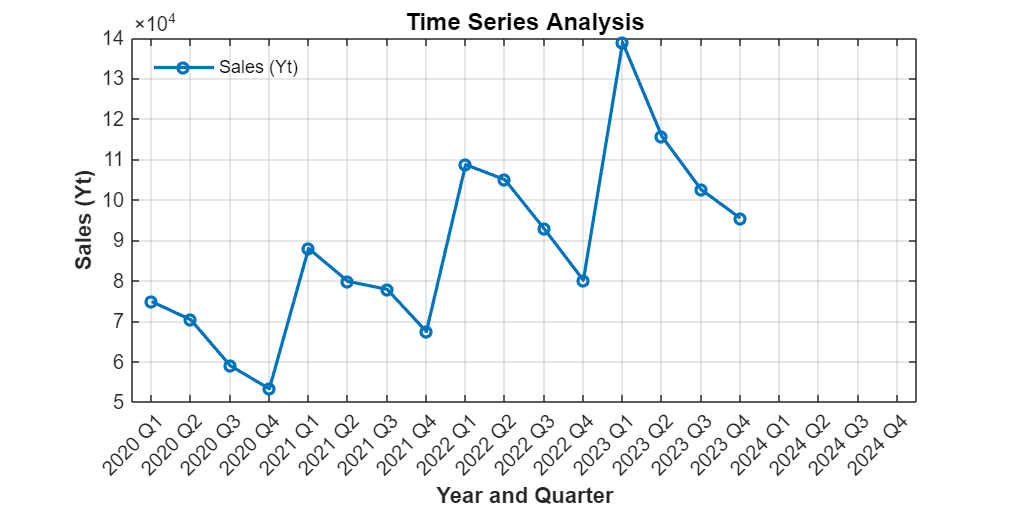

% Purpose: Visualise quarterly sales over time

% Convert Year_Quarter to categorical (preserves order)
Data.Year_Quarter = strcat(string(Data.Year), " Q", string(Data.Quarter));
Data.Year_Quarter = categorical(Data.Year_Quarter);

figure('Color','w','Position',[100 100 800 400]);
plot(Data.Year_Quarter, Data.Sales_Yt, '-o', 'Color', [0.00 0.45 0.74], ...
    'LineWidth',1.6, 'MarkerSize',5, ...
    'DisplayName','Sales (Yt)');

title('Time Series Analysis', 'FontWeight','bold', 'FontSize',12);
xlabel('Year and Quarter', 'FontWeight','bold');
ylabel('Sales (Yt)', 'FontWeight','bold');
grid on; xtickangle(45);
legend('Location','northwest','Box','off');

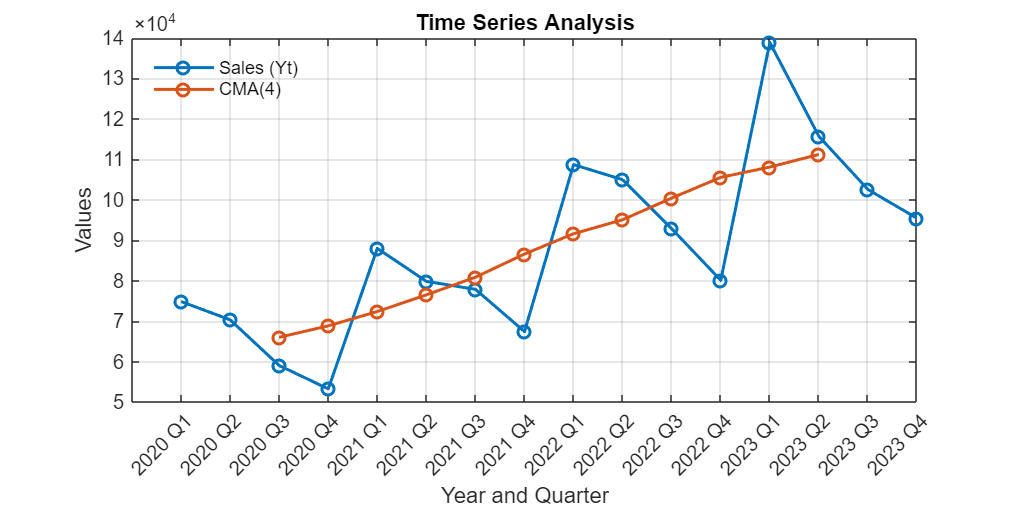

%% Visualise Sales and CMA(4) Over Time

% Create Year_Quarter labels 
Data.Year_Quarter = strcat(string(Data.Year), " Q", string(Data.Quarter));

% Use numeric x-axis for simplicity
x = 1:height(Data);

figure('Color','w', 'Position', [100 100 800 400]);

% Plot Sales (Yt)
plot(x, Data.Sales_Yt, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Sales (Yt)', 'Color', [0.00 0.45 0.74]);
hold on;

% Plot CMA(4)
plot(x, Data.CMA_4, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'CMA(4)', 'Color', [0.85 0.33 0.10]);

% Labels and title
title('Time Series Analysis');
xlabel('Year and Quarter');
ylabel('Values');
grid on;

% X-tick labels
set(gca, 'XTick', x, 'XTickLabel', Data.Year_Quarter);
xtickangle(45);

% Legend
legend('Location','northwest','Box','off');

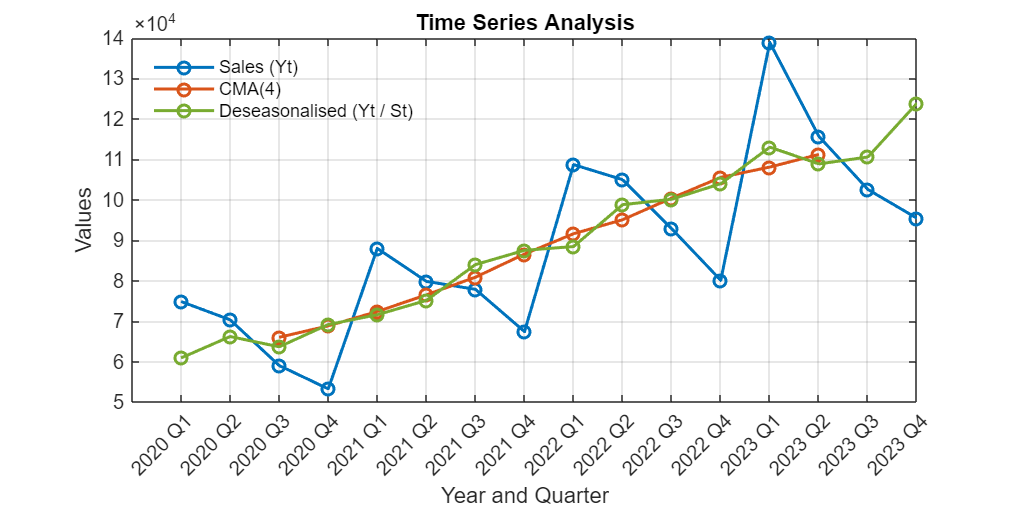

%% Time Series Plot: Sales, CMA(4), and Deseasonalised Yt

% Create Year_Quarter labels if not already done
Data.Year_Quarter = strcat(string(Data.Year), " Q", string(Data.Quarter));

% Use numeric x-axis for plotting
x = 1:height(Data);

% Create figure
figure('Color','w', 'Position', [100 100 800 400]);

% Plot original Sales
plot(x, Data.Sales_Yt, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Sales (Yt)', 'Color', [0.00 0.45 0.74]);
hold on;

% Plot CMA(4)
plot(x, Data.CMA_4, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'CMA(4)', 'Color', [0.85 0.33 0.10]);

% Plot Deseasonalised Yt
plot(x, Data.Deseasonalised_Yt,'-o', 'LineWidth', 1.5, 'Color', [0.47 0.67 0.19], ...
    'DisplayName', 'Deseasonalised (Yt / St)');

% Labels and title
title('Time Series Analysis');
xlabel('Year and Quarter');
ylabel('Values');
grid on;

% Custom x-axis labels
set(gca, 'XTick', x, 'XTickLabel', Data.Year_Quarter);
xtickangle(45);

% Add legend
legend('Location','northwest','Box','off');

## Step 5. Simple Linear Regression (Deseasonalised Yt → Trend Tt)

%% Linear Regression on Deseasonalised Data (Yt vs t)

% Filter non-NaN data for regression
valid_idx = ~isnan(Data.Deseasonalised_Yt);
t_valid = Data.t(valid_idx);
Yt_valid = Data.Deseasonalised_Yt(valid_idx);

n_valid = length(t_valid);  % number of valid data points

% Fit linear regression model: Y = a + b*t
p_lin = polyfit(t_valid, Yt_valid, 1);   % [slope, intercept]
Tt = polyval(p_lin, Data.t);       % predict full Tt values (even with NaN)

% Add prediction column
Data.Tt = Tt;

% Compute R² and Adjusted R² (use only first 16 known values)
Rsq   = @(y,yhat) 1 - sum((y - yhat).^2) / sum((y - mean(y)).^2);
AdjR2 = @(R2,n,p) 1 - (1-R2)*(n-1)/(n-p-1);  % p = 1 predictor (t)

% Restrict to first 16 time periods
range_idx = 1:16;
Y_actual = Data.Deseasonalised_Yt(range_idx);
Y_pred   = Data.Tt(range_idx);

% Remove NaNs (optional, should be none if data is clean)
non_nan_idx = ~isnan(Y_actual) & ~isnan(Y_pred);
Y_actual = Y_actual(non_nan_idx);
Y_pred   = Y_pred(non_nan_idx);

% Evaluation metrics
MSE = mean((Y_actual - Y_pred).^2);
R2  = Rsq(Y_actual, Y_pred);
AdjR2_val = AdjR2(R2, numel(Y_actual), 1);

% Display results
fprintf('\nLinear Regression on Deseasonalised Sales:\n');


Linear Regression on Deseasonalised Sales:


fprintf('Regression Equation: ŷ = %.3f·t + %.3f\n', p_lin(1), p_lin(2));

Regression Equation: ŷ = 4134.358·t + 53966.456


fprintf('R²     = %.4f\n', R2);

R²     = 0.9737


fprintf('Adj R² = %.4f\n', AdjR2_val);

Adj R² = 0.9718


fprintf('MSE    = %.4f\n', MSE);

MSE    = 9823114.4414



% Display table with key outputs
RegressionSummary = table(p_lin(2), p_lin(1), R2, AdjR2_val, MSE, ...
    'VariableNames', {'Intercept','Slope','R2','AdjR2','MSE'});
disp('=== Linear Regression Summary Table ===');

=== Linear Regression Summary Table ===


disp(RegressionSummary);

    Intercept    Slope       R2        AdjR2        MSE    
    _________    ______    _______    _______    __________

      53966      4134.4    0.97367    0.97179    9.8231e+06




% Display main data table (showing trend Tt)
disp('=== Updated Data Table with Trend Component (Tt) ===');

=== Updated Data Table with Trend Component (Tt) ===


disp(Data);

    t     Year    Quarter     Sales_Yt       CMA_4       St_with_It    St_without_It    Deseasonalised_Yt    Year_Quarter        Tt    
    __    ____    _______    __________    __________    __________    _____________    _________________    ____________    __________

     1    2020       1            74841           NaN         NaN          1.2291               60893         "2020 Q1"           58101
     2    2020       2            70324           NaN         NaN          1.0626               66183         "2020 Q2"           62235
     3    2020       3            59016         65999     0.89419         0.92722               63648         "2020

## Test the model

## Step 6. Predictive power (R^2)

Model Evaluation Metrics

- R² → Proportion of explained variance

- Adj R² → Penalises unnecessary complexity

- Standard Error (Root MSE) → Typical prediction error

%% Regression Statistics Summary Table (Linear Model)

% Total Sum of Squares (SST)
SST = sum((Y_actual - mean(Y_actual)).^2);

% Regression Sum of Squares (SSR)
SSR = sum((Y_pred - mean(Y_actual)).^2);

% Residual Sum of Squares (SSE)
SSE = sum((Y_actual - Y_pred).^2);   % Or SST - SSR

% Degrees of freedom
df_total = numel(Y_actual) - 1;
df_reg   = 1;                        % one predictor (t)
df_res   = df_total - df_reg;

% Mean Squares
MSR = SSR / df_reg;
MSE_anova = SSE / df_res;

% -------------------------------------------

MultipleR    = sqrt(R2);              % Multiple R = √R²
RSquared     = R2;
AdjRSquared  = AdjR2_val;             % Adjusted R²
StdError     = sqrt(MSE);             % Standard error is √MSE
n_obs        = numel(Y_actual);       % Number of fitted observations

% Create summary table
StatLabels = {'Multiple R'; 'R Square'; 'Adjusted R Square'; ...
              'Standard Error'; 'Observations'};
StatValues = [MultipleR; RSquared; AdjRSquared; StdError; n_obs];

RegressionStatsTable = table(StatValues, ...
    'RowNames', StatLabels, ...
    'VariableNames', {'Value'});

disp('=== Regression Statistics Summary Table ===');

=== Regression Statistics Summary Table ===


disp(RegressionStatsTable);

                          Value 
                         _______

    Multiple R           0.98675
    R Square             0.97367
    Adjusted R Square    0.97179
    Standard Error        3134.2
    Observations              16



## Step 7. Significance of model (p-value, ANOVA)

**Model Definition & Hypotheses**

We model the data using:

        
$$y=\textrm{ax}+b$$


Hypotheses for ANOVA  F-Test (overall model):

        
$$\begin{array}{l}
H_0 :a=0\\
H_1 :a\not= 0
\end{array}$$
 

% F-statistic & p-value
Fstat = MSR / MSE_anova;
pF = 1 - fcdf(Fstat, df_reg, df_res);

% ANOVA Table
ANOVA = table([df_reg; df_res; df_total], ...
              [SSR; SSE; SST], ...
              [MSR; MSE_anova; NaN], ...
              [Fstat; NaN; NaN], ...
              [pF; NaN; NaN], ...
              'VariableNames', {'df','SS','MS','F','pValue'}, ...
              'RowNames', {'Regression','Residual','Total'});

disp('=== ANOVA Table (Linear Model) ===');

=== ANOVA Table (Linear Model) ===


disp(ANOVA);

                  df        SS            MS          F         pValue  
                  __    __________    __________    ______    __________

    Regression     1    5.8116e+09    5.8116e+09    517.67    1.8603e-12
    Residual      14    1.5717e+08    1.1226e+07       NaN           NaN
    Total         15    5.9688e+09           NaN       NaN           NaN



%% Coefficient Significance Table (Linear Model)

% Recreate Design Matrix X
X = [ones(size(t_valid)), t_valid];
Y = Yt_valid;
beta = (X' * X) \ (X' * Y);

% Standard Errors
Cov_b = MSE * pinv(X' * X); 
se_b  = sqrt(diag(Cov_b));

% t-statistics & p-values
tcoef = beta ./ se_b;
pcoef = 2 * (1 - tcdf(abs(tcoef), df_res));


% Build coefficient significance table
CoefTable = table({'b (slope)'; 'a (intercept)'}, flipud(beta), flipud(se_b), ...
                  flipud(tcoef), flipud(pcoef), ...
    'VariableNames', {'Term','Estimate','StdError','tStat','pValue'});

disp('=== Coefficient Significance Table (Linear Model) ===');

=== Coefficient Significance Table (Linear Model) ===


disp(CoefTable);

          Term           Estimate    StdError    tStat       pValue  
    _________________    ________    ________    ______    __________

    {'b (slope)'    }     4134.4      169.98     24.323    7.4651e-13
    {'a (intercept)'}      53966      1643.6     32.835     1.199e-14




% Fit quality summary
fprintf('\nFit Quality:\n');


Fit Quality:


fprintf('R² = %.4f  (%.1f%% variance explained)\n', R2, R2 * 100);

R² = 0.9737  (97.4% variance explained)


fprintf('Adjusted R² = %.4f\n', AdjR2_val);

Adjusted R² = 0.9718


fprintf('F(%d,%d) = %.3f, p = %.5f\n\n', df_reg, df_res, Fstat, pF);

F(1,14) = 517.671, p = 0.00000



## Step 8. Normality Test of Residuals

A core regression assumption is that residuals follow a **normal distribution**, which justifies: Valid ANOVA, *F-tests*, **p-values, **Confidence and prediction intervals, Reliable statistical inference.

If residuals significantly deviate from normality, model conclusions may be unreliable.

Null vs. Alternative:

        $H_0$:Residuals follow a Normal distribution

        $H_1$:Residuals are NOT normally distributed

If p-value > 0.05 → **Normality assumption satisfied**

**Industry Lens (data science relevance)**

- Residual diagnostics help ensure **model interpretability & stability**, required in regulated AI domains (finance, healthcare).

- Before replacing models with black-box ML (e.g., neural networks), statistical regression shows **why** performance issues exist.

%% Residual Analysis: Descriptive Statistics and Outlier Detection (Linear Model)
%% Residuals from Linear Model (Deseasonalised Yt - Tt)

% Residuals = Actual - Predicted
Data.Residual = Data.Deseasonalised_Yt - Data.Tt;


% Filter valid residuals again (if not already done)
valid_res = ~isnan(Data.Residual);
t_vals    = Data.t(valid_res);
Tt_vals   = Data.Tt(valid_res);
Residuals = Data.Residual(valid_res);

% -------------------------------------------------------
% Create and display residuals table
ResidualsTable = table(t_vals, Tt_vals, Residuals, ...
    'VariableNames', {'t','Tt','Residual'});

disp('=== Residuals Table (Linear Model) ===');

=== Residuals Table (Linear Model) ===


disp(ResidualsTable);

    t         Tt        Residual
    __    __________    ________

     1         58101     2792.5 
     2         62235     3947.5 
     3         66370    -2721.4 
     4         70504    -1349.3 
     5         74638    -3057.8 
     6         78773    -3651.3 
     7         82907     1063.2 
     8         87041     462.62 
     9         91176    -2738.3 
    10         95310     3477.4 
    11         99444     694.47 
    12    1.0358e+05     398.13 
    13    1.0771e+05     5299.4 
    14    1.1185e+05    -2981.7 
    15    1.1598e+05    -5399.9 
    16    1.2012e+05     3764.5 




% Descriptive statistics
mean_res   = mean(Residuals);
std_res    = std(Residuals);
min_res    = min(Residuals);
max_res    = max(Residuals);
median_res = median(Residuals);
Q1_res     = quantile(Residuals, 0.25);
Q3_res     = quantile(Residuals, 0.75);
IQR_res    = Q3_res - Q1_res;
LB_res     = Q1_res - 1.5 * IQR_res;
UB_res     = Q3_res + 1.5 * IQR_res;

% Display summary table
DescStats = table(mean_res, std_res, median_res, Q1_res, Q3_res, ...
    IQR_res, LB_res, UB_res, min_res, max_res, ...
    'VariableNames', {'Mean','StdDev','Median','Q1','Q3', ...
                      'IQR','LowerBound','UpperBound','Min','Max'});

disp('=== Descriptive Stats and Outlier Bounds for Residuals ===');

=== Descriptive Stats and Outlier Bounds for Residuals ===


disp(DescStats);

       Mean       StdDev    Median     Q1       Q3     IQR     LowerBound    UpperBound      Min       Max  
    __________    ______    ______    _____    ____    ____    __________    __________    _______    ______

    4.0927e-12     3237     430.38    -2860    3135    5995      -11852        12127       -5399.9    5299.4



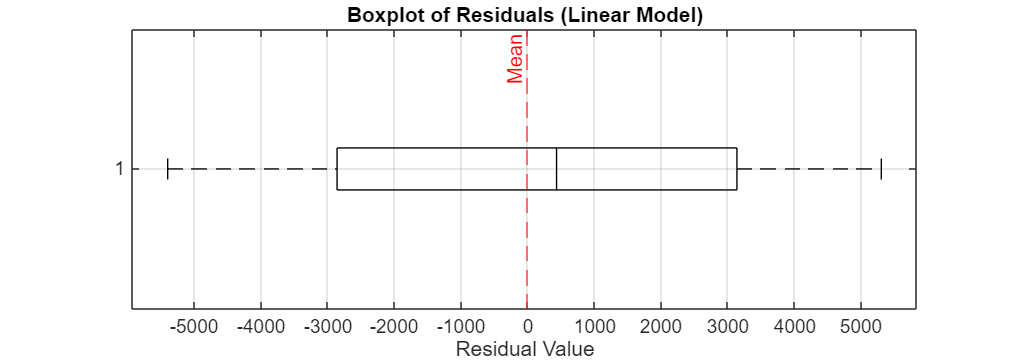


% Box plot
figure('Color','w', 'Position', [100 100 700 250]);
boxplot(Residuals, 'Orientation', 'horizontal', 'Colors','k', 'Symbol','r+');
title('Boxplot of Residuals (Linear Model)');
xlabel('Residual Value');
xline(mean_res, '--r', 'Mean','LabelHorizontalAlignment','left');
grid on;

## **Step 9. Histogram & Normality Test (Chi-Square) for Residuals**

%% Histogram and Normality (Chi-Square) Test for Residuals

% Sturges’ rule for number of bins
n_bins = round(1 + 3.322 * log10(length(Residuals)));

% Observed Histogram data
[observed_freq, bin_edges] = histcounts(Residuals, n_bins);

% Bin centres
bin_centres = bin_edges(1:end-1) + diff(bin_edges)/2;



% Normal distribution CDF at bin edges
cdf_vals = normcdf(bin_edges, mean_res, std_res);

% Bin-wise probabilities (from CDF differences)
bin_probs = diff(cdf_vals);

% Expected frequencies
expected_freq = bin_probs * length(Residuals);

% Chi-square test statistic (with continuity correction optional)
Chi2_vals = (observed_freq - expected_freq).^2 ./ expected_freq;
Chi2_total = sum(Chi2_vals);

% Degrees of freedom (bins - estimated parameters - 1)
df_chi = n_bins - 2 - 1;

% p-value
p_chi = 1 - chi2cdf(Chi2_total, df_chi);


### Visualisation

% Create and display table
ChiSquareTable = table(bin_centres', observed_freq', expected_freq', Chi2_vals', ...
    'VariableNames', {'Bin_Centre','Observed','Expected','ChiSq_Value'});

disp('=== Chi-Square Goodness-of-Fit Table ===');

=== Chi-Square Goodness-of-Fit Table ===


disp(ChiSquareTable);

    Bin_Centre    Observed    Expected    ChiSq_Value
    __________    ________    ________    ___________

      -4850          1         1.5138       0.17437  
      -2550          5         3.2988       0.87726  
       -250          4         4.4291      0.041577  
       2050          2         3.6649       0.75634  
       4350          4         1.8686        2.4312  




fprintf('Chi-square Statistic = %.4f\n', Chi2_total);

Chi-square Statistic = 4.2808


fprintf('Degrees of Freedom   = %d\n', df_chi);

Degrees of Freedom   = 2


fprintf('p-value              = %.5f\n\n', p_chi);

p-value              = 0.11761



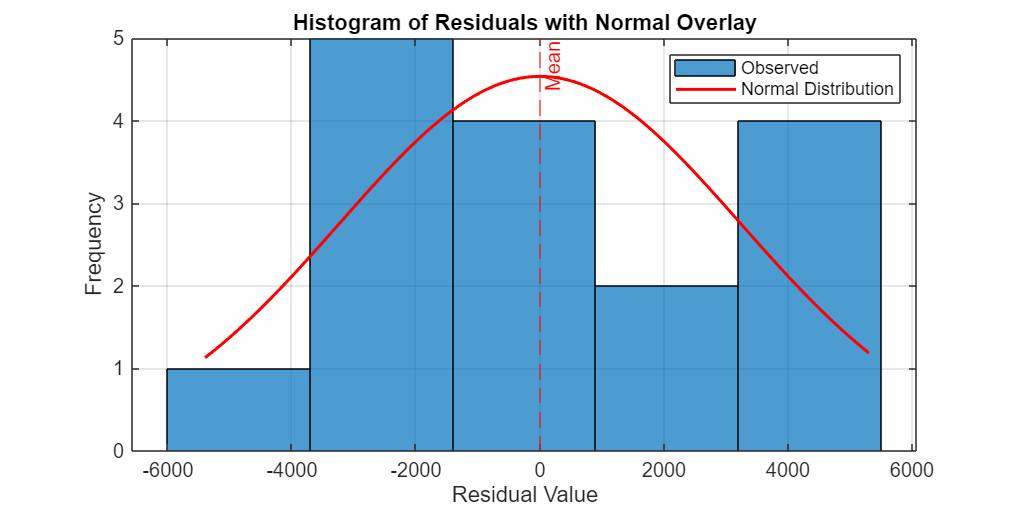


% Histogram with normal overlay
figure('Color','w', 'Position', [100 100 800 400]);
histogram(Residuals, n_bins, 'FaceAlpha', 0.7, 'EdgeColor','k');
hold on;
x_vals = linspace(min(Residuals), max(Residuals), 100);
y_vals = normpdf(x_vals, mean_res, std_res) * diff(bin_edges(1:2)) * length(Residuals);
plot(x_vals, y_vals, 'r-', 'LineWidth', 1.5, 'DisplayName','Normal PDF');
xline(mean_res, '--r', 'Mean');
title('Histogram of Residuals with Normal Overlay');
xlabel('Residual Value'); ylabel('Frequency');
legend('Observed','Normal Distribution','Location','northeast');
grid on;

## Step 10. Residual Plots: Constant Variance and Independence Assumption

A valid regression model requires residuals to be:

-   Randomly scattered around zero (no pattern)

-   Same variability across fitted values (no funneling)

-   Not dependent on observation order (independently collected samples)

If these conditions hold → model errors are "well-behaved.". 

If violated → consider transformation or different model structure.

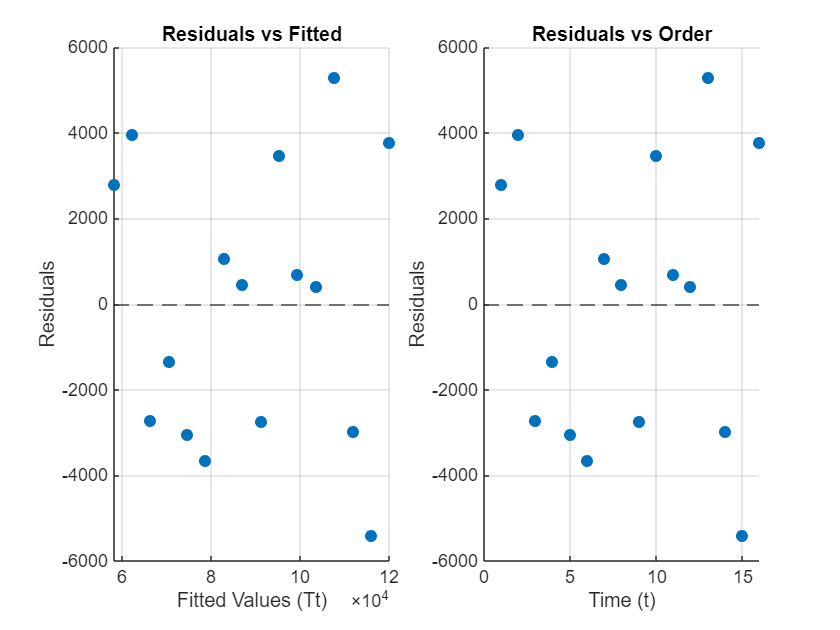

% Residuals vs Fitted (Tt)
figure('Color','w');
subplot(1,2,1);
scatter(Data.Tt(valid_res), Residuals, 'filled');
yline(0, '--k');
xlabel('Fitted Values (Tt)');
ylabel('Residuals');
title('Residuals vs Fitted');
grid on;

% Residuals vs Time Order
subplot(1,2,2);
scatter(Data.t(valid_res), Residuals, 'filled');
yline(0, '--k');
xlabel('Time (t)');
ylabel('Residuals');
title('Residuals vs Order');
grid on;

## Step 11. Predictions 

%% Forecasting with St and Tt (Linear Model)
% Forecast = St * Tt
Data.Forecast = Data.St_without_It .* Data.Tt;

% Create Year_Quarter column
Data.Year_Quarter = strcat(string(Data.Year), " Q", string(Data.Quarter));

% Create summary forecast table
ForecastTable = table(Data.Year_Quarter, Data.Sales_Yt, Data.CMA_4, ...
                      Data.Tt, Data.Forecast, ...
    'VariableNames', {'Year_Quarter','Sales_Yt','CMA4','Tt','Forecast'});

disp('=== Forecast Summary Table ===');

=== Forecast Summary Table ===


disp(ForecastTable);

    Year_Quarter     Sales_Yt        CMA4           Tt         Forecast 
    ____________    __________    __________    __________    __________

     "2020 Q1"           74841           NaN         58101         71409
     "2020 Q2"           70324           NaN         62235         66130
     "2020 Q3"           59016         65999         66370         61539
     "2020 Q4"           53249         68828         70504         54288
     "2021 Q1"           87976         72371         74638         91734
     "2021 Q2"           79822         76496         78773         83702
     "2021 Q3"           77859         80856         82907         76873
     "2021 Q4"           67409         86589         87041         67053
     "2022 Q1"      1.0869e+05         91607         91176    1.1206e+05
     "2022 Q2"      1.0497

% Convert Year and Quarter to "Year Q#" format
Data.Year_Quarter = strcat(string(Data.Year), " Q", string(Data.Quarter));

% Convert to categorical for plotting
x_labels = categorical(Data.Year_Quarter);
x_labels = reordercats(x_labels, Data.Year_Quarter);  % Preserve original order



### **Visualisation of Predictions**

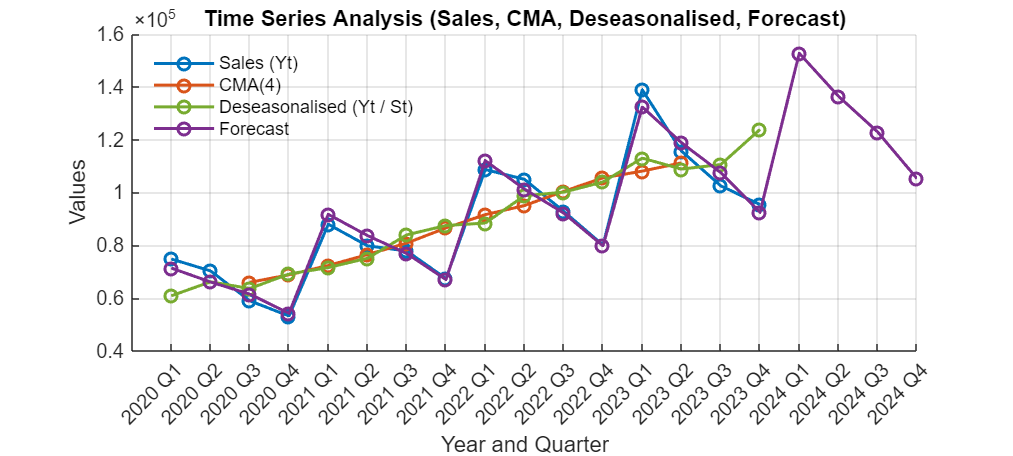

% Create Year_Quarter labels (if not already available)
Data.Year_Quarter = strcat(string(Data.Year), " Q", string(Data.Quarter));
x = 1:height(Data);  % x-axis as numeric index

figure('Color','w', 'Position', [100 100 1000 450]); 
hold on; grid on;

% Plot Sales (Yt)
plot(x, Data.Sales_Yt, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Sales (Yt)', ...
    'Color', [0.00 0.45 0.74]);

% Plot CMA(4)
if any(strcmp('CMA_4', Data.Properties.VariableNames))
    plot(x, Data.CMA_4, '-o', 'LineWidth', 1.5, ...
        'DisplayName', 'CMA(4)', ...
        'Color', [0.85 0.33 0.10]);
end

% Plot Deseasonalised Yt
plot(x, Data.Deseasonalised_Yt, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Deseasonalised (Yt / St)', ...
    'Color', [0.47 0.67 0.19]);

% Plot Forecast 
plot(x, Data.Forecast, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Forecast', ...
    'Color', [0.49 0.18 0.56]);

% Style and annotate
title('Time Series Analysis (Sales, CMA, Deseasonalised, Forecast)', 'FontWeight', 'bold');
xlabel('Year and Quarter');
ylabel('Values');
legend('Location','northwest','Box','off');

% Custom X-axis labels with Year_Quarter
set(gca, 'XTick', x, 'XTickLabel', Data.Year_Quarter);
xtickangle(45);
set(gca, 'FontSize', 10);

### Predictions: Forecasting t=16(2023-Quarter 4) and t=20(2024-Quarter 4)

Why uncertainty matters:Forecasting is not just about estimating a number. We must quantify how precise the estimate is.

%% Prediction Intervals and Visualisation (Linear Forecast Model)

alpha = 0.05;                       % 95% prediction level
prediction_level = 1 - alpha;
valid_idx = ~isnan(Data.Residual);  % use only valid residuals
t_valid = Data.t(valid_idx);

% Core statistics
x_bar = mean(t_valid);
s_x   = std(t_valid);
n     = numel(t_valid);
tcrit = tinv(1 - alpha/2, n - 1);   % critical t-value
RSE   = sqrt(sum(Data.Residual(valid_idx).^2) / (n - 2));   % residual std error

% Time values for prediction
t_new = [16; 20];
k = numel(t_new);

% Preallocate
SE_pred  = zeros(k,1);
LowerB   = zeros(k,1);
UpperB   = zeros(k,1);
PointPred = zeros(k,1);

% Compute prediction interval for each t_new
for i = 1:k
    x = t_new(i);

    % Find corresponding Forecast value
    if any(Data.t == x)
        PointPred(i) = Data.Forecast(Data.t == x);
    else
        PointPred(i) = polyval(p_lin, x);  % fallback if forecast not present
    end

    % Standard Error of Prediction (full formula)
    SE_pred(i) = RSE * sqrt(1 + 1/n + ((x - x_bar)^2) / ((s_x^2) * (n - 1)));

    % Prediction Interval bounds
    LowerB(i) = PointPred(i) - tcrit * SE_pred(i);
    UpperB(i) = PointPred(i) + tcrit * SE_pred(i);
end

% Half-width of prediction error term
ErrorTerm = tcrit .* SE_pred;

% Combine into summary table
Prediction_Table = table(t_new, repmat(tcrit, k, 1), SE_pred, RSE.*ones(k,1), ...
                         LowerB, PointPred, UpperB, ErrorTerm, ...
    'VariableNames', {'t','t_value','SE_Pred','RSE','LowerBound','PointPred','UpperBound','ErrorTerm'});

disp('=== Prediction Interval Summary (Linear Forecast Model) ===');

=== Prediction Interval Summary (Linear Forecast Model) ===


disp(Prediction_Table);

    t     t_value    SE_Pred     RSE      LowerBound    PointPred     UpperBound    ErrorTerm
    __    _______    _______    ______    __________    __________    __________    _________

    16    2.1314     3712.9     3350.6      84618            92532    1.0045e+05     7913.8  
    20    2.1314     4036.7     3350.6      96668       1.0527e+05    1.1388e+05       8604  




fprintf('\nInterpretation:\n');


Interpretation:


fprintf('• Prediction Intervals computed using Student-t (df = %d).\n', n-1);

• Prediction Intervals computed using Student-t (df = 15).


fprintf('• SE_Pred = RSE × sqrt(1 + 1/n + ((x - x̄)²)/((s_x²)(n-1))).\n');

• SE_Pred = RSE × sqrt(1 + 1/n + ((x - x̄)²)/((s_x²)(n-1))).


fprintf('• 95%% PI = ŷ ± t × SE_Pred.\n\n');

• 95% PI = ŷ ± t × SE_Pred.



### **Visualisation of Predictions**

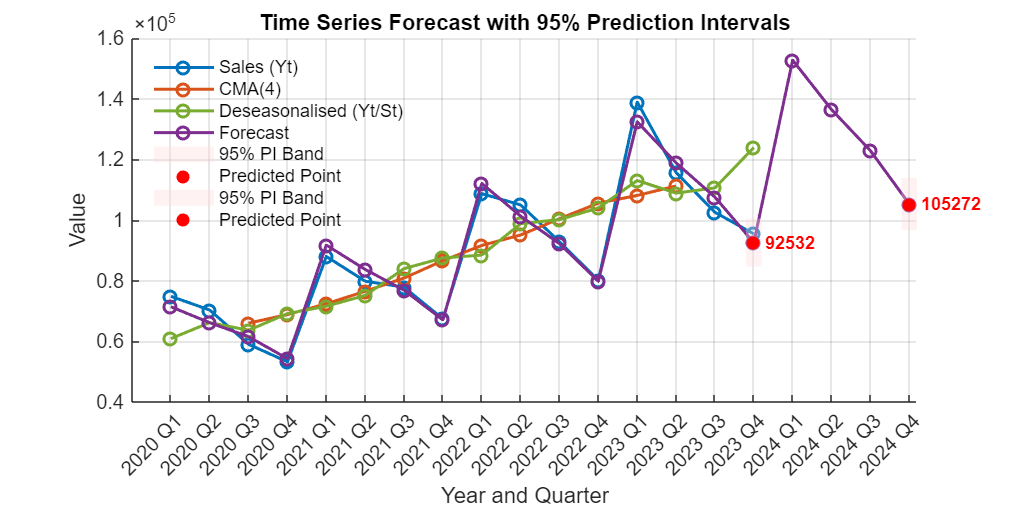

% X-axis labels
x_labels = strcat(string(Data.Year), " Q", string(Data.Quarter));
x = 1:height(Data);

figure('Color','w','Position',[100 100 1000 500]); hold on; grid on;

% 1) Existing time series
plot(x, Data.Sales_Yt, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Sales (Yt)', 'Color', [0.00 0.45 0.74]);
plot(x, Data.CMA_4, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'CMA(4)', 'Color', [0.85 0.33 0.10]);
plot(x, Data.Deseasonalised_Yt, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Deseasonalised (Yt/St)', 'Color', [0.47 0.67 0.19]);
plot(x, Data.Forecast, '-o', 'LineWidth', 1.5, ...
    'DisplayName', 'Forecast', 'Color', [0.49 0.18 0.56]);

% 2) Plot prediction intervals at t_new
for i = 1:k
    t_idx = find(Data.t == t_new(i));
    if isempty(t_idx)
        continue
    end
    x_pos = t_idx;
    y_pred = PointPred(i);
    L = LowerB(i);
    U = UpperB(i);

    % Fill vertical prediction interval band (narrow)
    fill([x_pos-0.2 x_pos+0.2 x_pos+0.2 x_pos-0.2], ...
         [L L U U], [1.0 0.85 0.85], 'EdgeColor','none', 'FaceAlpha',0.35, ...
         'DisplayName','95% PI Band');

    % Point prediction
    plot(x_pos, y_pred, 'ro', 'MarkerFaceColor','r', 'DisplayName','Predicted Point');

    % Label predicted value
    text(x_pos + 0.3, y_pred, sprintf('%.0f', y_pred), ...
        'Color','r','FontSize',9,'FontWeight','bold');
end

% Formatting
title('Time Series Forecast with 95% Prediction Intervals', 'FontWeight','bold');
xlabel('Year and Quarter');
ylabel('Value');
set(gca, 'XTick', x, 'XTickLabel', x_labels);
xtickangle(45);
legend('Location','northwest','Box','off','FontSize',9);
set(gca,'FontSize',10);


fprintf('\nInterpretation of Prediction Plot:\n');


Interpretation of Prediction Plot:


fprintf('• Red dots mark point predictions at selected time steps.\n');

• Red dots mark point predictions at selected time steps.


fprintf('• Shaded bands represent 95%% prediction intervals.\n');

• Shaded bands represent 95% prediction intervals.


fprintf('• Forecast line (purple) shows modelled trend beyond actual data.\n\n');

• Forecast line (purple) shows modelled trend beyond actual data.

